1.    Filtered Gaussian Noise Method

Generate g that is ouput of  a first order LPF with coeffiecient zeta for different f_mT with input is white Gaussian noise source with PSD=S 

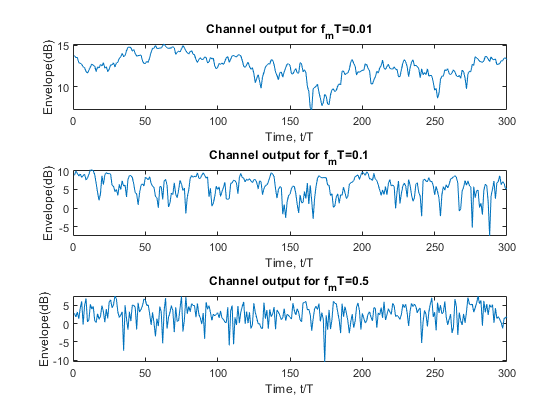

clear
S=1;
PSD=S;
f_mT=[0.01,0.1,0.5];
%Set T=1
T=1;
f_m=[0.01,0.1,0.5]/T;
zeta=2-cos(pi*f_mT/2)-sqrt((2-cos(pi*f_mT/2)).^2-1);
s=sqrt((1+zeta)./(1-zeta))*PSD;
tap=10^4;
%generate zero-mean Gaussian random variables with variance s(i)
w1=normrnd(0,s(1)^2,2,tap);
w2=normrnd(0,s(2)^2,2,tap);
w3=normrnd(0,s(3)^2,2,tap);
% Initialize g=[gI,gQ]
g_1=[0;0];
g_2=[0;0];
g_3=[0;0];
for i=1:tap
    g_1(:,i+1)=zeta(1)*g_1(:,i)+(1-zeta(1))*w1(:,i);
    g_2(:,i+1)=zeta(2)*g_2(:,i)+(1-zeta(2))*w2(:,i);
    g_3(:,i+1)=zeta(3)*g_3(:,i)+(1-zeta(3))*w3(:,i);
end
% Since the value of envelope around g(0) is significantly affected by the initial value of g,
% take the value of tail
for i=1:300
    env_1(i)=norm(g_1(:,i+length(g_1)-300));
    env_2(i)=norm(g_2(:,i+length(g_2)-300));
    env_3(i)=norm(g_3(:,i+length(g_3)-300));
end
%compute autocorrelation with normalization
for i=1:length([0:f_mT(1):10])
    Rn_1(i)=(1-zeta(1))/(1+zeta(1))*s(1)^2*zeta(1)^(i-1);
end
for i=1:length([0:f_mT(2):10])
    Rn_2(i)=(1-zeta(2))/(1+zeta(2))*s(2)^2*zeta(2)^(i-1);
end

for i=1:length([0:f_mT(3):10])
    Rn_3(i)=(1-zeta(3))/(1+zeta(3))*s(3)^2*zeta(3)^(i-1);
end
%compute autocorrelation without normalization
%fixed time delay for each g
for i=1:300
    R_1(i)=(1-zeta(1))/(1+zeta(1))*s(1)^2*zeta(1)^(i-1);
    R_2(i)=(1-zeta(2))/(1+zeta(2))*s(2)^2*zeta(2)^(i-1);
    R_3(i)=(1-zeta(3))/(1+zeta(3))*s(3)^2*zeta(3)^(i-1);
end

% figures of envelope
figure
subplot(3,1,1)
plot(10*log10(env_1))
titleStr=sprintf('Channel output for f_mT=%0.2f',f_mT(1));
title(titleStr)
xlabel("Time, t/T")
ylabel('Envelope(dB)')

subplot(3,1,2)
plot(10*log10(env_2))
titleStr=sprintf('Channel output for f_mT=%0.1f',f_mT(2));
title(titleStr)
xlabel("Time, t/T")
ylabel('Envelope(dB)')

subplot(3,1,3)
plot(10*log10(env_3))
titleStr=sprintf('Channel output for f_mT=%0.1f',f_mT(3));
title(titleStr)
xlabel("Time, t/T")
ylabel('Envelope(dB)')

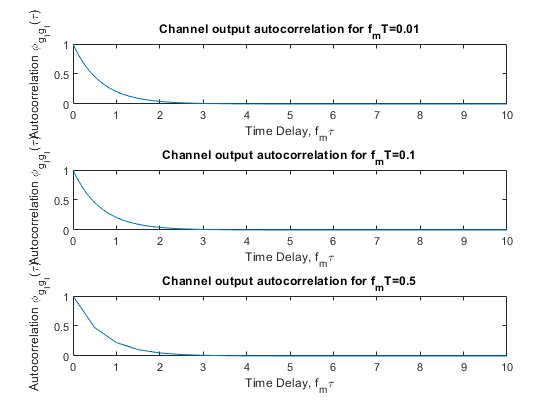



%figures of autocorrelation with normaliztion
figure
subplot(3,1,1)
plot([0:f_mT(1):10],Rn_1)
titleStr=sprintf('Channel output autocorrelation for f_mT=%0.2f',f_mT(1));
title(titleStr)
xlabel("Time Delay, f_m\tau")
ylabel('Autocorrelation \phi_{g_Ig_I}(\tau)')

subplot(3,1,2)
plot([0:f_mT(2):10],Rn_2)
titleStr=sprintf('Channel output autocorrelation for f_mT=%0.1f',f_mT(2));
title(titleStr)
xlabel("Time Delay, f_m\tau")
ylabel('Autocorrelation \phi_{g_Ig_I}(\tau)')

subplot(3,1,3)
plot([0:f_mT(3):10],Rn_3)
titleStr=sprintf('Channel output autocorrelation for f_mT=%0.1f',f_mT(3));
title(titleStr)
xlabel("Time Delay, f_m\tau")
ylabel('Autocorrelation \phi_{g_Ig_I}(\tau)')

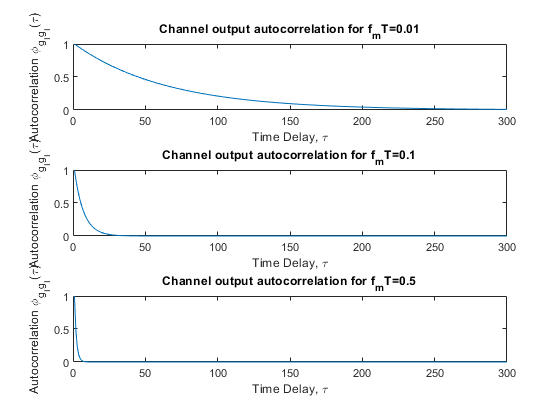


%figures of autocorrelation without normaliztion
figure
subplot(3,1,1)
plot(R_1)
titleStr=sprintf('Channel output autocorrelation for f_mT=%0.2f',f_mT(1));
title(titleStr)
xlabel("Time Delay, \tau")
ylabel('Autocorrelation \phi_{g_Ig_I}(\tau)')

subplot(3,1,2)
plot(R_2)
titleStr=sprintf('Channel output autocorrelation for f_mT=%0.1f',f_mT(2));
title(titleStr)
xlabel("Time Delay, \tau")
ylabel('Autocorrelation \phi_{g_Ig_I}(\tau)')

subplot(3,1,3)
plot(R_3)
titleStr=sprintf('Channel output autocorrelation for f_mT=%0.1f',f_mT(3));
title(titleStr)
xlabel("Time Delay, \tau")
ylabel('Autocorrelation \phi_{g_Ig_I}(\tau)')